% Información del archivo .h5
path = "..\hdf5\A_RS_140819\LFP.h5";
filename = strrep(path, '\', '\\');
dataset = '/LFP';
info = h5info(filename, dataset);
num_times = info.Dataspace.Size(1);

signal = h5read(filename, dataset);

for i=1:6
    f=2^i;
    mask = subsample_mask(f);
    m = mean(signal(:, mask), 2);
    s = std(signal(:, mask), 1, 2);
    mean_path = sprintf("subsample_mean_f_%d", f);
    std_path = sprintf("subsample_std_f_%d", f);
    save(mean_path, "m");
    save(std_path, "s");
end

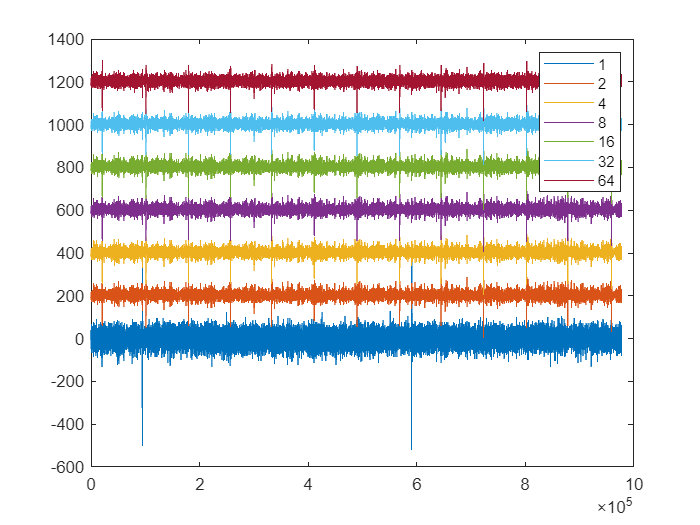

    "1"    "2"    "4"    "8"    "16"    "32"    "64"



clear
clf
for i=0:6
    f=2^i;
    mean_path = sprintf("subsample_mean_f_%d", f);
    load(mean_path, "m");
    plot(m+200*i);
    hold on
end

legend(string(2.^(0:6)));

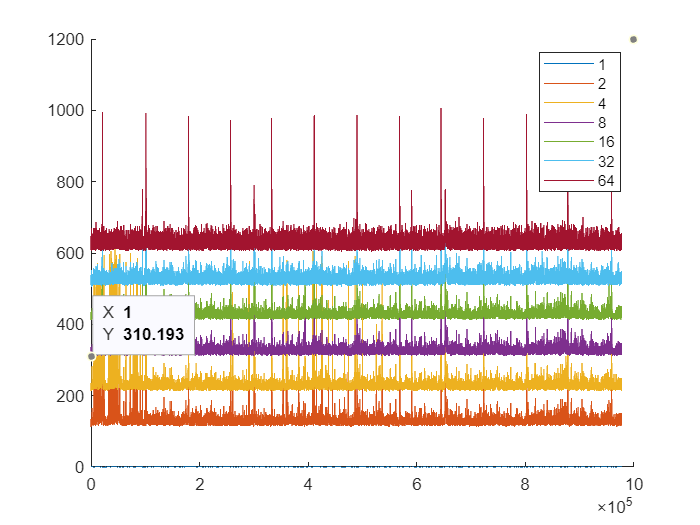

clf
for i=0:6
    hold on
    f=2^i;
    std_path = sprintf("subsample_std_f_%d", f);
    load(std_path, "s");
    plot(s+100*i);
end
legend(string(2.^(0:6)));

length(m)

ans = 1013080

length(m(~isnan(m)))

ans = 977289

box_lengths=floor(logspace(2, 6, 100))';
for i=0:6
    f=2^i;
    i
    mean_path = sprintf("subsample_mean_f_%d", f);
    load(mean_path, "m");
    [~,F] = DFA_fun(m(~isnan(m)), box_lengths, 1);
    dfa_path = sprintf("subsample_dfa_f_%d", f);
    save(dfa_path, "box_lengths", "F");
end

i = 0

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

clear
clf
figure(1);
for i=0:6
    f=2^i;
    i
    dfa_path = sprintf("subsample_dfa_f_%d.mat", f);
    load(dfa_path, "box_lengths", "F");
    hold on;
    plot(log10(box_lengths), log10(F), LineStyle="--", Marker=".", MarkerSize=10);
end

i = 0

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

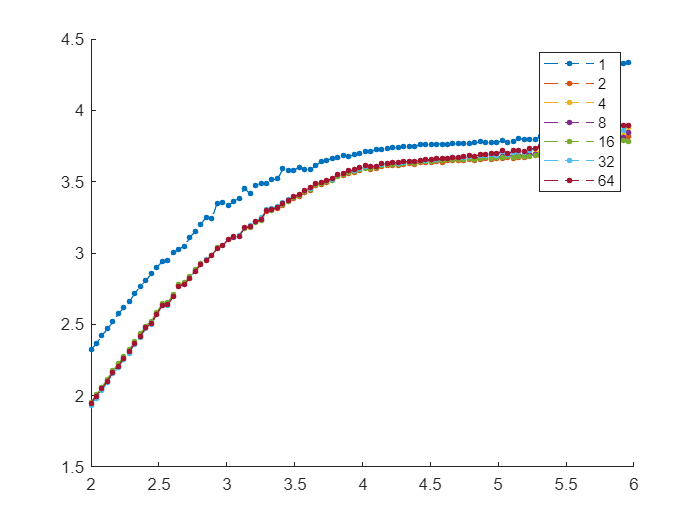

legend(string(2.^(0:6)));
hold off;

clear
clf
for i=0:6
    f=2^i;
    i
    dfa_path = sprintf("subsample_dfa_f_%d.mat", f);
    load(dfa_path, "box_lengths", "F");
    % calculo la derivada logaritmica (alfa)
    alpha = diff(log10(F))./diff(log10(box_lengths));
    hold on;
    plot(log10(box_lengths(2:end)), alpha, LineStyle="--", Marker=".", MarkerSize=10);
end

i = 0

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

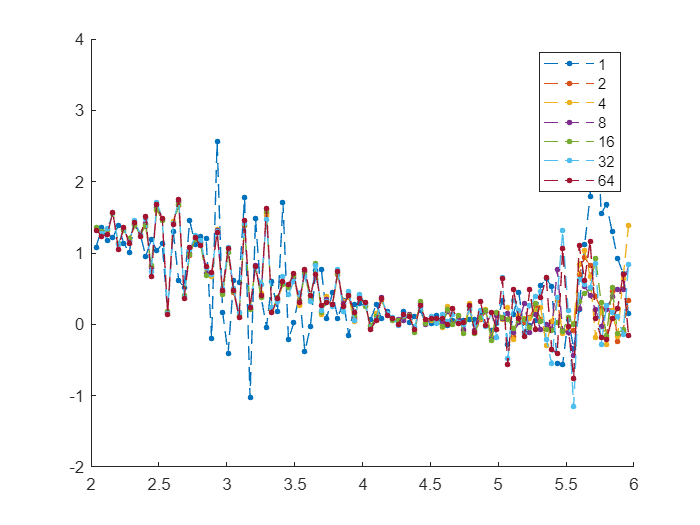

legend(string(2.^(0:6)));
hold off

size(F)

ans =    100     1


size(box_lengths)

ans =      1   100
